## **Covid Detection Transfer Learning with leave one patient out validation (resnet50)**

## Load Pretrained Network

net = resnet18;

Use `analyzeNetwork` to display an interactive visualization of the network architecture and detailed information about the network layers.

% analyzeNetwork(net);

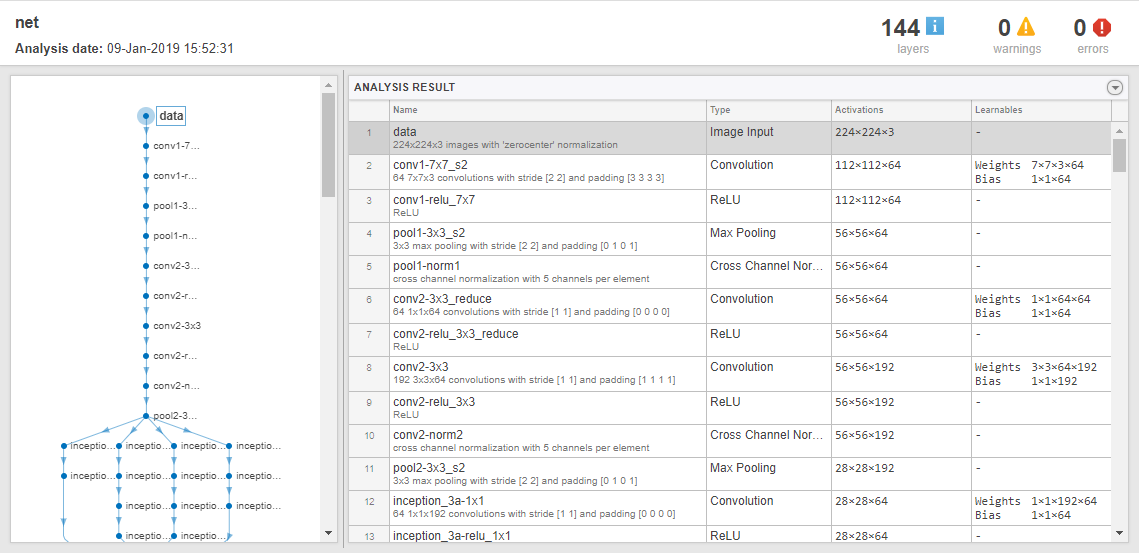

net.Layers(1);
inputSize = net.Layers(1).InputSize;

## Replace Final Layers

Extract the layer graph from the trained network. If the network is a `SeriesNetwork` object, such as AlexNet, VGG-16, or VGG-19, then convert the list of layers in `net.Layers` to a layer graph.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Find the names of the two layers to replace. You can do this manually or you can use the supporting function [findLayersToReplace](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically. 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer];

In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (5, in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

% numClasses = numel(categories(imdsTrain.Labels));
numClasses = 2;

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

To check that the new layers are connected correctly, plot the new layer graph and zoom in on the last layers of the network.

% figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
% plot(lgraph);
% ylim([0,10]);

## Freeze Initial Layers and Training options

layers = lgraph.Layers;
connections = lgraph.Connections;

frozen = 1;
layers(1:frozen) = freezeWeights(layers(1:frozen));
lgraph = createLgraphUsingConnections(layers,connections);

% Training options
options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'Verbose',false);

## Performance Data Initialization and other variables

numPatients = 384;
% Initialize true positive, true negative, false positive, false negative.
sum_TP = 0;
sum_TN = 0;
sum_FP = 0;
sum_FN = 0;

% Matrix to hold performance data for each train and test run 
% columns (accuracy,fscore,avg_fscore)
performance = zeros([0,2]);
fscore = zeros(0);

## Load Data and Train Network for every One Patient Out Validation (384 patients total)

% Loop for doing each one patient out validation and then training the
% model and getting performance results
for patientNum = 1:numPatients
    [fullPatientList,isCOVID] = leaveOneOutSetup(patientNum); % Prep file structure and data ('leave_out') folder
    
    % Data splits: one patient in validation, the rest in training.
    imdsTrain = imageDatastore(fullfile('leave_out','train'),'IncludeSubfolders',true,'LabelSource','foldernames');
    imdsValidation = imageDatastore(fullfile('leave_out','validation'),'IncludeSubfolders',true,'LabelSource','foldernames');
    
    %***Image augmentation with variability***%
    % Use an augmented image datastore to automatically resize the training images. 
    % Specify additional augmentation operations to perform on the training images: 
    % randomly flip the training images along the vertical axis and randomly translate them 
    % up to 30 pixels and scale them up to 10% horizontally and vertically. 
    % Data augmentation helps prevent the network from overfitting and memorizing 
    % the exact details of the training images.  
    
    %{
    pixelRange = [-30 30];
    scaleRange = [0.9 1.1];
    imageAugmenter = imageDataAugmenter( ...
        'RandXReflection',true, ...
        'RandXTranslation',pixelRange, ...
        'RandYTranslation',pixelRange, ...
        'RandXScale',scaleRange, ...
        'RandYScale',scaleRange);
    
    augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
        'DataAugmentation',imageAugmenter, 'ColorPreprocessing','gray2rgb');
    %}
    
    %  Standard image augmentation
    augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain,"ColorPreprocessing","gray2rgb");
    augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation,"ColorPreprocessing","gray2rgb");
    
   
    %  Train network   
    net = trainNetwork(augimdsTrain,lgraph,options);
    


## Classify Test Images

Classify the test images using the fine-tuned network, and calculate the test accuracy.

    [YPred,probs] = classify(net,augimdsValidation);

    % Extract the class labels from the test data.
    YTest = imdsValidation.Labels;
    
    % Calculate accuracy
    accuracy = mean(YPred == YTest);
    
    % Get confusion matrix values.
    conf_values = confusionmat(YTest, YPred);
    
    % Add to total categories (for COVID).
    if(isCOVID == 1)
        sum_TP = sum_TP + conf_values(1,1);
        TP = conf_values(1,1);
        sum_FN = sum_FN + conf_values(1,2);
        FN = conf_values(1,2);
        sum_FP = sum_FP + conf_values(2,1);
        FP = conf_values(2,1);
        sum_TN = sum_TN + conf_values(2,2);
        TN = conf_values(2,2);
        
        % Calculate Recall
        Recall = TP /(TP + FN);
        if isnan(Recall)
            Recall = 0;
        end
        % Calculate Precision
        Precision = TP / (TP + FP);
        if isnan(Precision)
            Precision = 0;
        end
        % Calculate FScore
        FScore = (2*(Precision * Recall)) / (Precision+Recall);
        if isnan(FScore)
            FScore = 0;
        end
    end

    % Add to total categories (for nonCOVID) The confusion matrix for these patients
    % are reversed.
    if(isCOVID == 0)
        sum_TN = sum_TN + conf_values(1,1);
        TN = conf_values(1,1);
        sum_FP = sum_FP + conf_values(1,2);
        FP = conf_values(1,2);
        sum_FN = sum_FN + conf_values(2,1);
        FN = conf_values(2,1);
        sum_TP = sum_TP + conf_values(2,2);
        TP = conf_values(2,2);
        
        % Calculate Recall
        Recall = TN /(TN + FP);
        if isnan(Recall)
            Recall = 0;
        end
        % Calculate Precision
        Precision = TN / (TN + FN);
        if isnan(Precision)
            Precision = 0;
        end
        % Calculate FScore
        FScore = (2*(Precision * Recall)) / (Precision+Recall);
        if isnan(FScore)
            FScore = 0;
        end
    end
 
    fscore = [fscore FScore];
 
    performance(patientNum, 1) = accuracy;
    performance(patientNum, 2) = FScore;
    
    % Print patient info and results
     fprintf('%d >> %s, ACC=%.3f, F1=%.3f\n',patientNum,fullPatientList{patientNum},accuracy,FScore)

1 >> Patient 1, ACC=1.000, F1=1.000
2 >> Patient 10, ACC=0.000, F1=0.000
3 >> Patient 100, ACC=0.000, F1=0.000
4 >> Patient 101, ACC=0.000, F1=0.000
5 >> Patient 102, ACC=1.000, F1=1.000
6 >> Patient 103, ACC=1.000, F1=1.000
7 >> Patient 104, ACC=0.000, F1=0.000
8 >> Patient 105, ACC=0.000, F1=0.000
9 >> Patient 106, ACC=0.250, F1=0.400
10 >> Patient 107, ACC=1.000, F1=1.000
11 >> Patient 108, ACC=1.000, F1=1.000
12 >> Patient 109, ACC=1.000, F1=1.000
13 >> Patient 11, ACC=1.000, F1=1.000
14 >> Patient 110, ACC=1.000, F1=1.000
15 >> Patient 111, ACC=1.000, F1=1.000
16 >> Patient 112, ACC=1.000, F1=1.000
17 >> Patient 113, ACC=1.000, F1=1.000
18 >> Patient 114, ACC=1.000, F1=1.000
19 >> Patient 115, ACC=0.500, F1=0.667
20 >> Patient 116, ACC=0.000, F1=0.000
21 >> Patient 117, ACC=1.000, F1=1.000
22 >> Patient 118, ACC=0.500, F1=0.667
23 >> Patient 119, ACC=1.000, F1=1.000
24 >> Patient 12, ACC=1.000, F1=1.000
25 >> Patient 120, ACC=1.000, F1=1.000
26 >> Patient 121, ACC=1.000, F1=1.000


end % End function for leave on out validation training on all patients

## Ending performance stats

% Print ending performance matrix
disp('**************************************************************************')

**************************************************************************


disp('*                          Final Perfromance Report                      *')

*                          Final Perfromance Report                      *


disp('**************************************************************************')

**************************************************************************



performance

performance =     1.0000    1.0000
         0         0
         0         0
         0         0
    1.0000    1.0000
    1.0000    1.0000
         0         0
         0         0
    0.2500    0.4000
    1.0000    1.0000


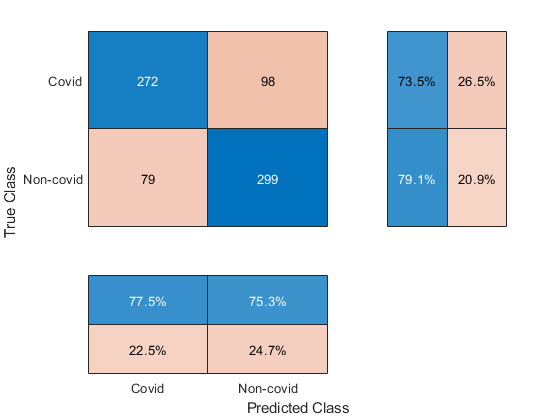


P = mean(performance);

% Get accuracy of combined confusion matrix.
combined_mat = [sum_TP, sum_FP ; sum_FN, sum_TN];
combined_accuracy = (sum(diag(combined_mat))/sum(sum(combined_mat)))*100;

% Display combined confusion chart.
figure;
conf = confusionchart(combined_mat,["Covid", "Non-covid"],'RowSummary','row-normalized','ColumnSummary','column-normalized');


% avgAccuracy = P(1)
avgF1Score = P(2)

avgF1Score = 0.4469


sDev_accuracy = std(performance(:,1))

sDev_accuracy = 0.3783

sDev_F1 = std(performance(:,2))

sDev_F1 = 0.4898




% save('leave_one_resnet18.mat','avgAccuracy','avgF1Score','sDev_accuracy','sDev_F1');



